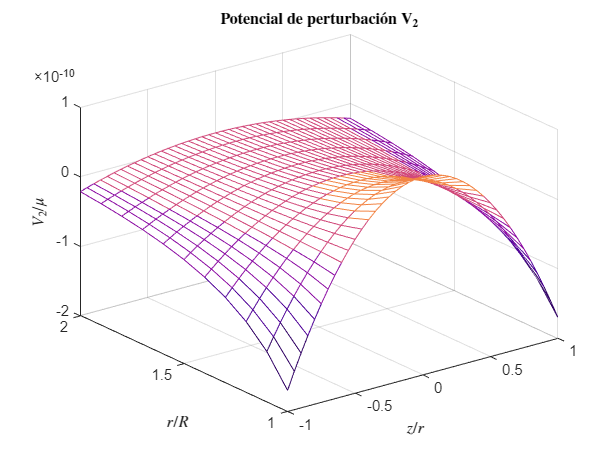

clear; clc; close all; % Limpia variables, consola y ventanas gráficas 

% Crear carpeta 'figuras' si no existe
if ~exist('figuras', 'dir')
    mkdir('figuras');
end

zr = -1:0.05:1; % Coordenada adimensional z/r (de -1 a 1)
R = 6378137; % Radio ecuatorial terrestre en metros
r = R:0.1*R:2*R; % Rango de radios

% Coeficientes armónicos zonales de potencial gravitatorio
J2 = 1.082635854E-3;
J3 = -2.532435346E-6;
J4 = -1.619331205E-6;

[zr, r] = meshgrid(zr, r); % Crea mallas 2D de coordenadas z/r y r

% Polinomios de Legendre asociados a cada término Jn
P2 = @(p) (1.5*p.^2 - 0.5);
P3 = @(p) (2.5*p.^3 - 1.5*p);
P4 = @(p) (35/8*p.^4 - 15/4*p.^2 + 3/8);

% Potenciales perturbativos U2, U3 y U4 (divididos por la constante gravitacional μ)
U2 = -J2 * R^2 ./ r.^3 .* P2(zr);
U3 = -J3 * R^3 ./ r.^4 .* P3(zr);
U4 = -J4 * R^4 ./ r.^5 .* P4(zr);

% Paleta de colores "plasma"
plasma = [0.20 0.02 0.40;
          0.32 0.02 0.60;
          0.56 0.07 0.65;
          0.82 0.29 0.48;
          0.95 0.52 0.27];

% Gráfica de U2
fig1 = figure;
mesh(zr, r/R, U2)
xlabel('$z/r$', 'Interpreter', 'latex')
ylabel('$r/R$', 'Interpreter', 'latex')
zlabel('$V_2/\mu$', 'Interpreter', 'latex')
title('\textbf{Potencial de perturbaci\''on $\bf{V_2}$}', 'Interpreter', 'latex')
colormap(plasma)
saveas(fig1, fullfile('figuras', 'U2.svg'))

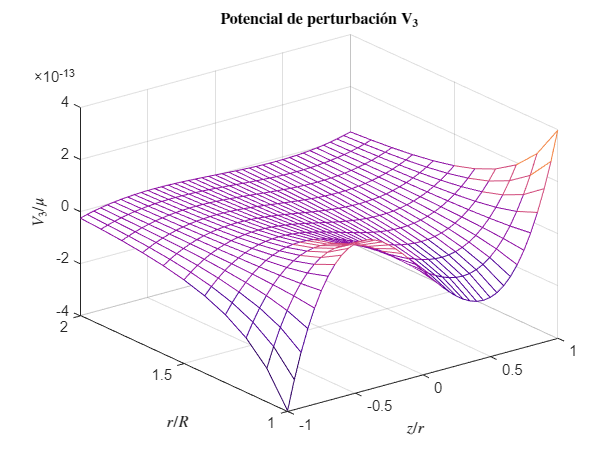


% Gráfica de U3
fig2 = figure;
mesh(zr, r/R, U3)
xlabel('$z/r$', 'Interpreter', 'latex')
ylabel('$r/R$', 'Interpreter', 'latex')
zlabel('$V_3/\mu$', 'Interpreter', 'latex')
title('\textbf{Potencial de perturbaci\''on $\bf{V_3}$}', 'Interpreter', 'latex')
colormap(plasma)
saveas(fig2, fullfile('figuras', 'U3.svg'))

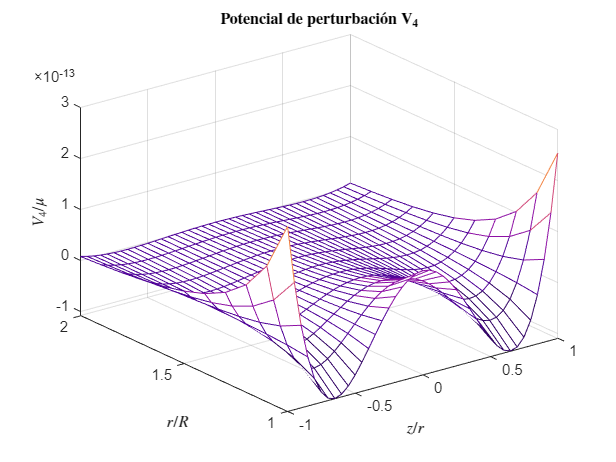


% Gráfica de U4
fig3 = figure;
mesh(zr, r/R, U4)
xlabel('$z/r$', 'Interpreter', 'latex')
ylabel('$r/R$', 'Interpreter', 'latex')
zlabel('$V_4/\mu$', 'Interpreter', 'latex')
title('\textbf{Potencial de perturbaci\''on $\bf{V_4}$}', 'Interpreter', 'latex')
colormap(plasma)
saveas(fig3, fullfile('figuras', 'U4.svg'))